# NN Train, Validation and Test 

%% network traning
[net_E, info_E]= trainNetwork(XTrain,YTrain_E,nn_small,options_E);

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:27 |       10.00% |       23.85% |       2.2259 |       2.0673 |          0.0010 |
|       1 |          50 |       00:00:34 |       70.00% |       64.58% |       0.7600 |       0.8331 |          0.0010 |
|       1 |         100 |       00:00:38 |       70.00% |       59.65% |       0.6474 |       0.8031 |          0.0010 |
|       1 |         150 |       00:00:43 |       75.00% |       84.55% |       0.5323 |       0.4835 |          0.0010 |
|       

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       25.00% |       20.62% |       1.5958 |       1.6176 |          0.0010 |
|       1 |          50 |       00:00:11 |       50.00% |       49.90% |       1.0433 |       1.1049 |          0.0010 |
|       1 |         100 |       00:00:15 |       65.00% |       63.30% |       0.9177 |       0.9353 |          0.0010 |
|       1 |         150 |       00:00:19 |       80.00% |       67.99% |       0.6883 |       0.7996 |          0.0010 |
|       

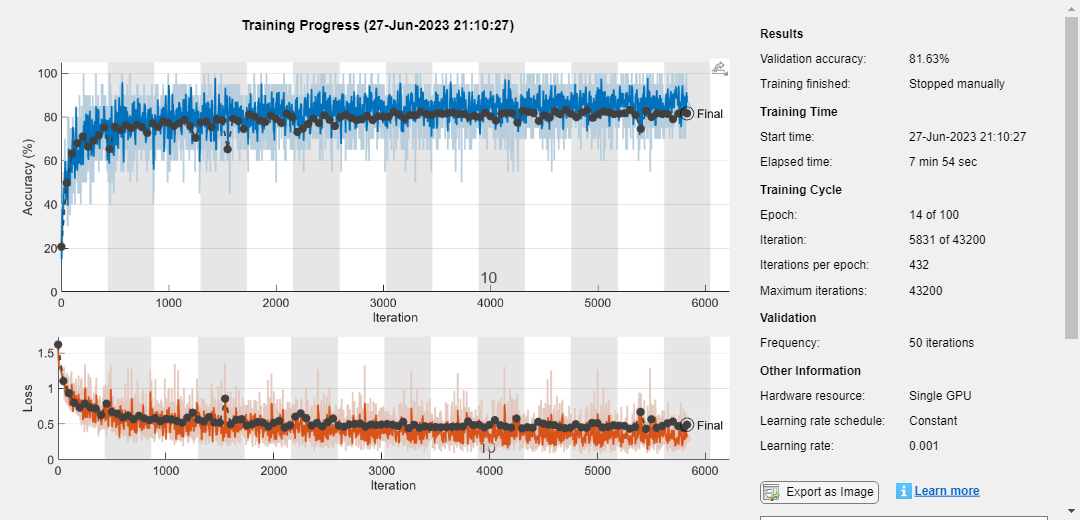

[net_F, info_F]= trainNetwork(XTrain,YTrain_F,nn_small,options_F);

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |        0.00% |        6.25% |       3.3389 |       3.1618 |          0.0010 |
|       1 |          50 |       00:00:13 |       10.00% |       18.61% |       2.6138 |       2.4017 |          0.0010 |
|       1 |         100 |       00:00:20 |       25.00% |       17.71% |       1.9761 |       2.2484 |          0.0010 |
|       1 |         150 |       00:00:27 |       35.00% |       31.11% |       1.8875 |       1.9685 |          0.0010 |
|       

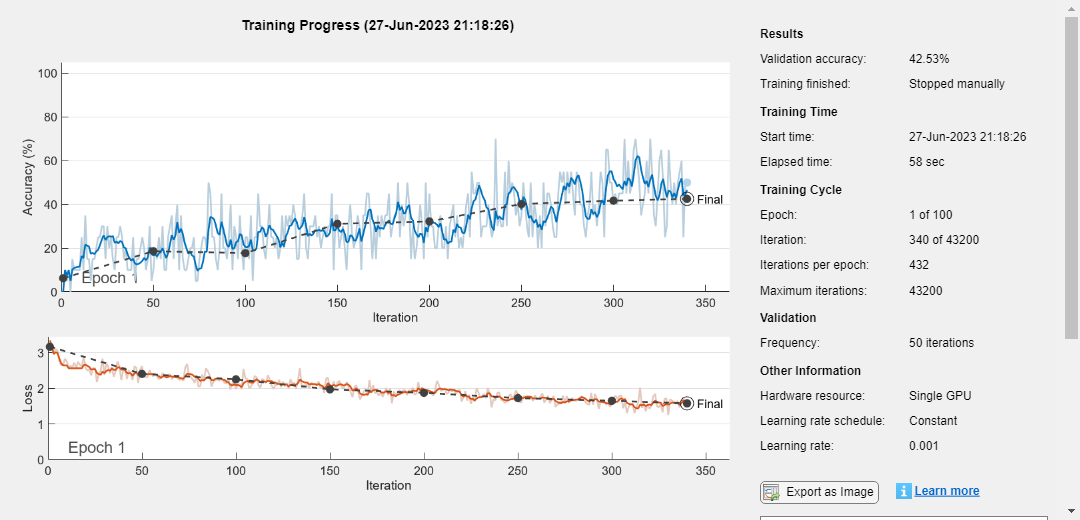

[net_EF, info_EF]= trainNetwork(XTrain,YTrain_EF,nn_large,options_EF);

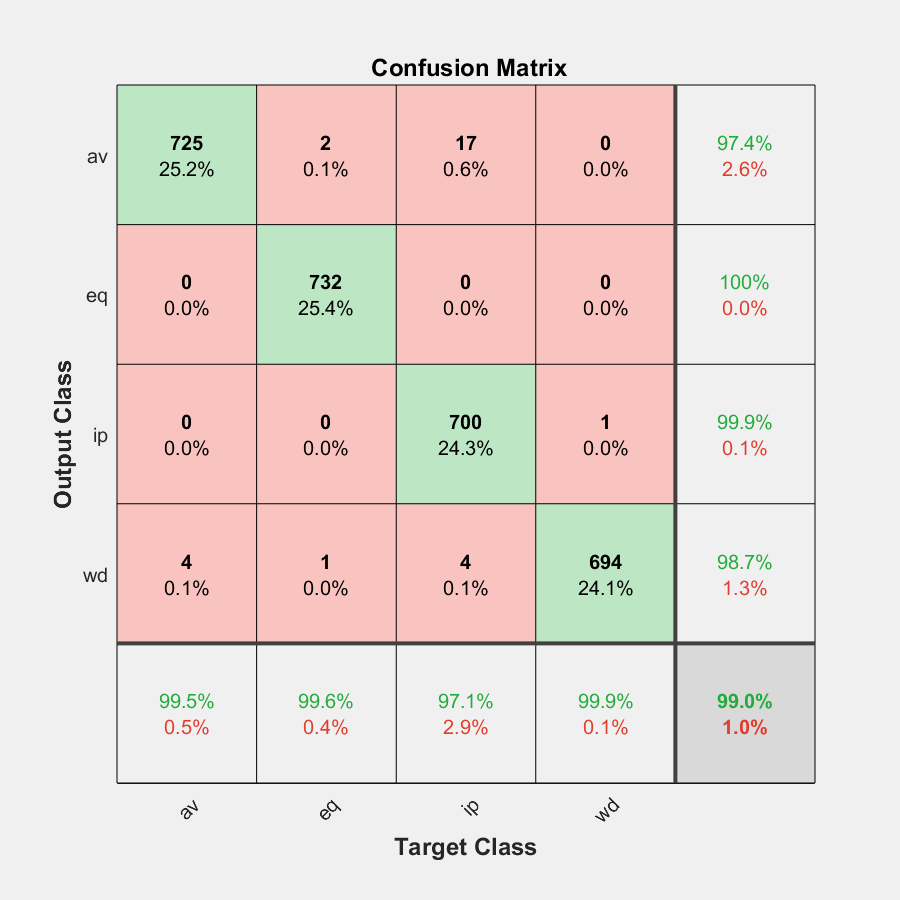


%% network classification
YPredicted_E = classify(net_E,XTest);
plotconfusion(YTest_E,YPredicted_E');


YPredicted_F = classify(net_F,XTest);
plotconfusion(YTest_F,YPredicted_F');

YPredicted_EF = classify(net_EF,XTest);
plotconfusion(YTest_EF,YPredicted_EF');

Error using matlab.ui.Figure/get
Invalid or deleted object.

Error in clf (line 112)
if ~isempty(get(fig,'CurrentAxes'))

Error in plotconfusion>setup_figure (line 226)
        clf(fig);

Error in 


%% network saving
save('net_E.mat','net_E');
save('net_F.mat','net_F');
save('net_EF.mat','net_EF');

save workspace_f.mat
% 
% figure
% subplot(2,1,1)
% plot(info.TrainingAccuracy); hold on;
% plot(info.ValidationAccuracy,'o'); legend('traning','validation')
% xlabel('iteration'); ylabel('accuracy,%'); grid on;
% set(gca,'FontSize',16);set(get(gca,'XLabel'),'FontSize',16); set(get(gca,'YLabel'),'FontSize',16); set(get(gca,'Title'),'FontSize',16);
% xlim([0,360]);
% subplot(2,1,2)
% plot(info.TrainingLoss); hold on;
% plot(info.ValidationLoss,'o'); legend('traning','validation')
% xlabel('iteration'); ylabel('loss'); grid on;
% set(gca,'FontSize',16);set(get(gca,'XLabel'),'FontSize',16); set(get(gca,'YLabel'),'FontSize',16); set(get(gca,'Title'),'FontSize',16);
% xlim([0,360]);
